# A simulation of a decoy BB84 link in fibre only

## 1. Choose parameters

wavelength=1550;                                                           %wavelength is measured in nm
time_gate_width=1E-9;                                                      %times are measured in s
spectral_filter_width=1;%consistent with wavelength, spectral width is measured in nm
repetition_rate = 100E6;                                                   %rep rate in Hz


## 2. Construct components

%2.1 source
source = components.Source(wavelength,"Repetition_Rate",repetition_rate);
%2.2 transmitter
t = fibre.FibreNode('Source',source,...
                    'Detector',components.Detector(wavelength,source.repetition_rate,...
                        time_gate_width,spectral_filter_width,...
                        'Preset','Perfect'),...
                        'LLA',[0,0,0]);

%2.3 detector
d = components.Detector(wavelength,source.repetition_rate,...
                        time_gate_width,spectral_filter_width,...
                        'Preset','Perfect');
%2.4 receiver
r = fibre.FibreNode('Detector',d, 'LLA',[100,0,0]);
%2.5 fibre
f = fibre.Fibre(1E5);%10km fibre

## 3 run

%3 run simulation
Result=fibre.qkdFibreSimulation(r,t,f,protocol.entanglementSingleDistribution);

## 4 Plot results

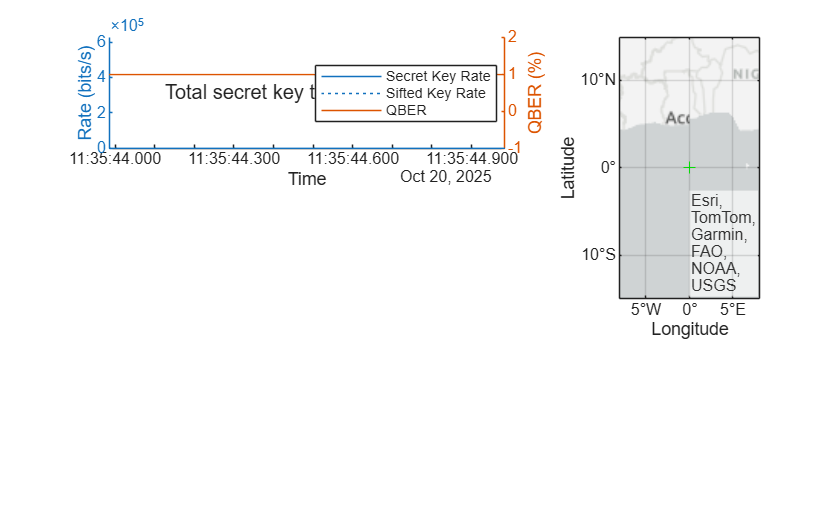

Error using geoplot (line 133)
Expected lat to be an array with all of the values <= 90.

Error in fibre.FibreSimulationResult/plot (line 173)
                geoplot(rx_loc.latitude, rx_loc.longitude, 'rx');
                ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

%4 plot results
Result.plot()